## **EECE 8395 - Medical Image Segmentation**

## **Project 3**

## **Tahsin Reasat**

## **ID: **000614908

## **All local functions are attached at the end of the script.**

clear 
close all
clc

## Task 1

## 1a) First we load our ground truth mandible and mandible segmentations from 3 raters

% data_dir='C:\Users\greas\Data\EECE_395';
data_dir='C:\Users\greas\Box\Vanderbilt_Vivobook_Windows\EECE_8395\EECE_395';
gt = ReadNrrd([data_dir '\0522c0001\structures\mandible.nrrd']);
t1 = ReadNrrd([data_dir '\0522c0001\structures\target1.nrrd']);
t2 = ReadNrrd([data_dir '\0522c0001\structures\target2.nrrd']);
t3 = ReadNrrd([data_dir '\0522c0001\structures\target3.nrrd']);

## 1b) Now we create surfaces for all of the volumetric segmentations.

gts = isosurface(gt.data,0.5);
gts.vertices = gts.vertices.*repmat(gt.voxsz,[length(gts.vertices),1]);
t1s = isosurface(t1.data,0.5);
t1s.vertices = t1s.vertices.*repmat(t1.voxsz,[length(t1s.vertices),1]);
t2s = isosurface(t2.data,0.5);
t2s.vertices = t2s.vertices.*repmat(t2.voxsz,[length(t2s.vertices),1]);
t3s = isosurface(t3.data,0.5);
t3s.vertices = t3s.vertices.*repmat(t3.voxsz,[length(t3s.vertices),1]);

## 1c) Display the surfaces in one figure

figure(1);clf
DisplayMesh(gts,[1,0,0],0.5);...
DisplayMesh(t1s,[0,1,0],0.5);...
DisplayMesh(t2s,[0,0,1],0.5);...
DisplayMesh(t3s,[0.5,0,0.5],0.5);...
legend('Ground Truth', 'Target1','Target2','Target3')

## 1d) Calculate volume

volume_gts=VolumeofMesh(gts);
volume_t1s=VolumeofMesh(t1s);
volume_t2s=VolumeofMesh(t2s);
volume_t3s=VolumeofMesh(t3s);

## 1e) Measure Dice similarity, mean symmetric absolute surface, Hausdorff distance between the ground truth and each of the three raters

## Dice

dice_t1_gt=dice(t1.data,gt.data);
dice_t2_gt=dice(t2.data,gt.data);
dice_t3_gt=dice(t3.data,gt.data);

## Mean symmetric absolute surface, and Hausdorff distance

[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t1s);
meandist_t1_gt=mean([mn1,mn2])
hausdorff_t1_gt=max([mx1,mx2])

[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t2s);
meandist_t2_gt=mean([mn1,mn2])
hausdorff_t2_gt=max([mx1,mx2])

[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t3s);
meandist_t3_gt=mean([mn1,mn2])
hausdorff_t3_gt=max([mx1,mx2])

## 1g) Create a majority vote segmentation from the three rater segmentations, measure its volume, and measure Dice similarity, Mean surface, and Hausdorff distances to the ground truth

mv = t1;
mv.data = t1.data + t2.data + t3.data > 1.5;
mvs = isosurface(mv.data,0.5);
mvs.vertices = mvs.vertices.*repmat(mv.voxsz,[length(mvs.vertices),1]);
[mn1,mn2,mx1,mx2]=SurfaceDistance(gts,mvs);
meandist_gt_mv=mean([mn1,mn2])
hausdorffmv=max([mx1,mx2])

## Task 2

## Define filepaths

filepaths_gt=glob([data_dir '\*\structures\mandible.nrrd']); 
% glob performs pattern matching of file and directory names based on
% wildcard characters. Downloaded from mathworks file exchange section.
filepaths_t1=glob([data_dir '\*\structures\target1.nrrd']);
filepaths_t2=glob([data_dir '\*\structures\target2.nrrd']);
filepaths_t3=glob([data_dir '\*\structures\target3.nrrd']);

## Initialize variables to store data

n_sample=10;
volume_gts_vec=zeros(1,n_sample);
volume_t1s_vec=zeros(1,n_sample);
volume_t2s_vec=zeros(1,n_sample);
volume_t3s_vec=zeros(1,n_sample);
volume_mvs_vec=zeros(1,n_sample);

tp1_vec=zeros(1,n_sample); 
tn1_vec=zeros(1,n_sample);
fp1_vec=zeros(1,n_sample);
fn1_vec=zeros(1,n_sample);
tp2_vec=zeros(1,n_sample); 
tn2_vec=zeros(1,n_sample);
fp2_vec=zeros(1,n_sample);
fn2_vec=zeros(1,n_sample);
tp3_vec=zeros(1,n_sample); 
tn3_vec=zeros(1,n_sample);
fp3_vec=zeros(1,n_sample);
fn3_vec=zeros(1,n_sample);

dice_t1_gt_vec=zeros(1,n_sample);
dice_t2_gt_vec=zeros(1,n_sample);
dice_t3_gt_vec=zeros(1,n_sample);
dice_t1_t2_vec=zeros(1,n_sample);
dice_t2_t3_vec=zeros(1,n_sample);
dice_t3_t1_vec=zeros(1,n_sample);
dice_mv_gt_vec=zeros(1,n_sample);

hausdorff_t1_gt_vec=zeros(1,n_sample);
hausdorff_t2_gt_vec=zeros(1,n_sample);
hausdorff_t3_gt_vec=zeros(1,n_sample);
hausdorff_mv_gt_vec=zeros(1,n_sample);
meandist_t1_gt_vec=zeros(1,n_sample);
meandist_t2_gt_vec=zeros(1,n_sample);
meandist_t3_gt_vec=zeros(1,n_sample);
meandist_gt_mv_vec=zeros(1,n_sample);

##  Compute data for the first 10 samples

for i= 1:n_sample
    tic
    gt = ReadNrrd(filepaths_gt{i});
    t1 = ReadNrrd(filepaths_t1{i});
    t2 = ReadNrrd(filepaths_t2{i});
    t3 = ReadNrrd(filepaths_t3{i});
    gts = isosurface(gt.data,0.5);
    gts.vertices = gts.vertices.*repmat(gt.voxsz,[length(gts.vertices),1]);
    t1s = isosurface(t1.data,0.5);
    t1s.vertices = t1s.vertices.*repmat(t1.voxsz,[length(t1s.vertices),1]);
    t2s = isosurface(t2.data,0.5);
    t2s.vertices = t2s.vertices.*repmat(t2.voxsz,[length(t2s.vertices),1]);
    t3s = isosurface(t3.data,0.5);
    t3s.vertices = t3s.vertices.*repmat(t3.voxsz,[length(t3s.vertices),1]);
    
    mv = t1;
    mv.data =double(t1.data + t2.data + t3.data > 1.5);
    mvs = isosurface(mv.data,0.5);
    mvs.vertices = mvs.vertices.*repmat(mv.voxsz,[length(mvs.vertices),1]);
        
    %% Calculate volume
    volume_gts=VolumeofMesh(gts);
    volume_t1s=VolumeofMesh(t1s);
    volume_t2s=VolumeofMesh(t2s);
    volume_t3s=VolumeofMesh(t3s);
    volume_mvs=VolumeofMesh(mvs);
    
    %% Calculate tp,tn,fp,fn 
    [tp1,fp1,tn1,fn1]=class_perf(gt.data,t1.data);
    [tp2,fp2,tn2,fn2]=class_perf(gt.data,t2.data);
    [tp3,fp3,tn3,fn3]=class_perf(gt.data,t3.data);
    
    %% Dice coefficient
    dice_t1_gt=dice(t1.data,gt.data);
    dice_t2_gt=dice(t2.data,gt.data);
    dice_t3_gt=dice(t3.data,gt.data);
    dice_t1_t2=dice(t1.data,t2.data);
    dice_t2_t3=dice(t2.data,t3.data);
    dice_t3_t1=dice(t3.data,t1.data);
    dice_mv_gt=dice(mv.data,gt.data);
    
    %% Mean symmetric absolute surface, and Hausdorff distance
    [meandist_t1_gt,hausdorff_t1_gt]=mean_hausdorff(gts,t1s);
    [meandist_t2_gt,hausdorff_t2_gt]=mean_hausdorff(gts,t2s);
    [meandist_t3_gt,hausdorff_t3_gt]=mean_hausdorff(gts,t3s);
    [meandist_t1_t2,hausdorff_t1_t2]=mean_hausdorff(t1s,t2s);    
    [meandist_t2_t3,hausdorff_t2_t3]=mean_hausdorff(t2s,t3s);
    [meandist_t3_t1,hausdorff_t3_t1]=mean_hausdorff(t3s,t1s);
    [meandist_gt_mv,hausdorff_gt_mv]=mean_hausdorff(gts,mvs);
   
    %% Store all data
    volume_gts_vec(i)=volume_gts;
    volume_t1s_vec(i)=volume_t1s;
    volume_t2s_vec(i)=volume_t2s;
    volume_t3s_vec(i)=volume_t3s;
    volume_mvs_vec(i)=volume_mvs;
    
    tp1_vec(i)=tp1; tn1_vec(i)=tn1;fp1_vec(i)=fp1;fn1_vec(i)=fn1;
    tp2_vec(i)=tp2; tn2_vec(i)=tn2;fp2_vec(i)=fp2;fn2_vec(i)=fn2;
    tp3_vec(i)=tp3; tn3_vec(i)=tn3;fp3_vec(i)=fp3;fn3_vec(i)=fn3;
    
    dice_t1_gt_vec(i)=dice_t1_gt;
    dice_t2_gt_vec(i)=dice_t2_gt;
    dice_t3_gt_vec(i)=dice_t3_gt;
    dice_t1_t2_vec(i)=dice_t1_t2;
    dice_t2_t3_vec(i)=dice_t2_t3;
    dice_t3_t1_vec(i)=dice_t3_t1;
    dice_mv_gt_vec(i)=dice_mv_gt;
    
    hausdorff_t1_gt_vec(i)=hausdorff_t1_gt;
    hausdorff_t2_gt_vec(i)=hausdorff_t2_gt;
    hausdorff_t3_gt_vec(i)=hausdorff_t3_gt;
    hausdorff_t1_t2_vec(i)=hausdorff_t1_t2;
    hausdorff_t2_t3_vec(i)=hausdorff_t2_t3;
    hausdorff_t3_t1_vec(i)=hausdorff_t3_t1;
    hausdorff_mv_gt_vec(i)=hausdorff_gt_mv;
    
    meandist_t1_gt_vec(i)=meandist_t1_gt;
    meandist_t2_gt_vec(i)=meandist_t2_gt;
    meandist_t3_gt_vec(i)=meandist_t3_gt;
    meandist_t1_t2_vec(i)=meandist_t1_t2;
    meandist_t2_t3_vec(i)=meandist_t2_t3;
    meandist_t3_t1_vec(i)=meandist_t3_t1;
    meandist_gt_mv_vec(i)=meandist_gt_mv;
    
    time_elapsed=toc;
%     split_path=strsplit(filepaths_gt{i},'\');
%     fprintf('%d. computation done for patient %s, time taken: %.2f minutes\n',...
%         i,split_path{end-2}, time_elapsed/60)
end

% save('project_3_v2.mat')

load('project_3_v2.mat')

## 2a) Overall confusion matrix

tp1_all=sum(tp1_vec);
tn1_all=sum(tn1_vec);
fp1_all=sum(fp1_vec);
fn1_all=sum(fn1_vec);
T_cf1=table([tp1_all; fn1_all],[fp1_all; tn1_all],...
'VariableNames',{'gt_negative','gt_positive'},...
'RowNames',{'t1_negative';'t1_positive'});
fprintf('Confusion matrix between ground truth and target1\n\n'); disp(T_cf1)

Confusion matrix between ground truth and target1

                   gt_negative    gt_positive
                   ___________    ___________

    t1_negative    1.6507e+05           4190 
    t1_positive          3817     3.5923e+08 




tp2_all=sum(tp2_vec);
tn2_all=sum(tn2_vec);
fp2_all=sum(fp2_vec);
fn2_all=sum(fn2_vec);
T_cf2=table([tp2_all; fn2_all],[fp2_all; tn2_all],...
'VariableNames',{'gt_negative','gt_positive'},...
'RowNames',{'t2_negative';'t2_positive'});
fprintf('Confusion matrix between ground truth and target2\n\n'); disp(T_cf2)

Confusion matrix between ground truth and target2

                   gt_negative    gt_positive
                   ___________    ___________

    t2_negative    1.6597e+05           3654 
    t2_positive          2913     3.5923e+08 




tp3_all=sum(tp3_vec);
tn3_all=sum(tn3_vec);
fp3_all=sum(fp3_vec);
fn3_all=sum(fn3_vec);
T_cf3=table([tp3_all; fn3_all],[fp3_all; tn3_all],...
'VariableNames',{'gt_negative','gt_positive'},...
'RowNames',{'t3_negative';'t3_positive'});
fprintf('Confusion matrix between ground truth and target3\n\n'); disp(T_cf3)

Confusion matrix between ground truth and target3

                   gt_negative    gt_positive
                   ___________    ___________

    t3_negative    1.4798e+05          35285 
    t3_positive         20903      3.592e+08 



## 2b) Sensitivity and Specificity of the targets

Se1=tp1_all/(tp1_all+fn1_all);
Sp1=tn1_all/(tn1_all+fp1_all);
Se2=tp2_all/(tp2_all+fn2_all);
Sp2=tn2_all/(tn2_all+fp2_all);
Se3=tp3_all/(tp3_all+fn3_all);
Sp3=tn3_all/(tn3_all+fp3_all);
T_sen_sp=table([Se1;Se2;Se3],[Sp1; Sp2; Sp3],...
'VariableNames',{'Sensitivity','Specificity'},...
'RowNames',{'t1';'t2';'t3'});
disp(T_sen_sp)

          Sensitivity    Specificity
          ___________    ___________

    t1       0.9774        0.99999  
    t2      0.98275        0.99999  
    t3      0.87623         0.9999  



## Task 3

## 3a) Code is in the livescript.

## 3b) The segmentations are shown in Task 1c

## 3c) Boxplot of overall results of Task 1d to 1g

## Volume

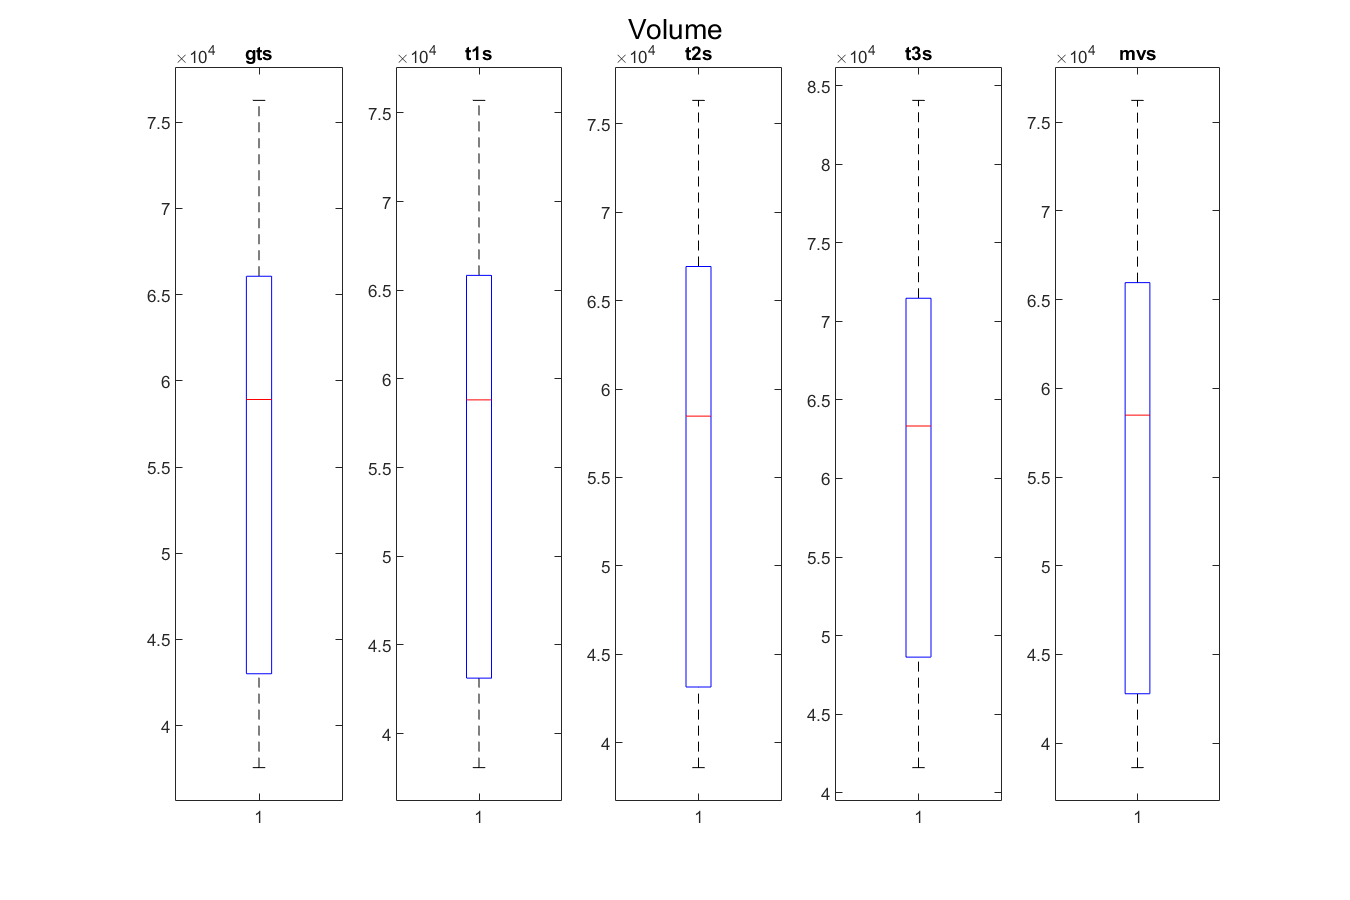

figure('Renderer', 'painters', 'Position', [10 10 900 600]);...
subplot(1,5,1); boxplot(volume_gts_vec);title('gts');...
subplot(1,5,2); boxplot(volume_t1s_vec);title('t1s');...
subplot(1,5,3); boxplot(volume_t2s_vec);title('t2s');...
subplot(1,5,4);boxplot(volume_t3s_vec);title('t3s');...
subplot(1,5,5);boxplot(volume_mvs_vec);title('mvs');...
sgtitle({'Volume',' '})

## Dice

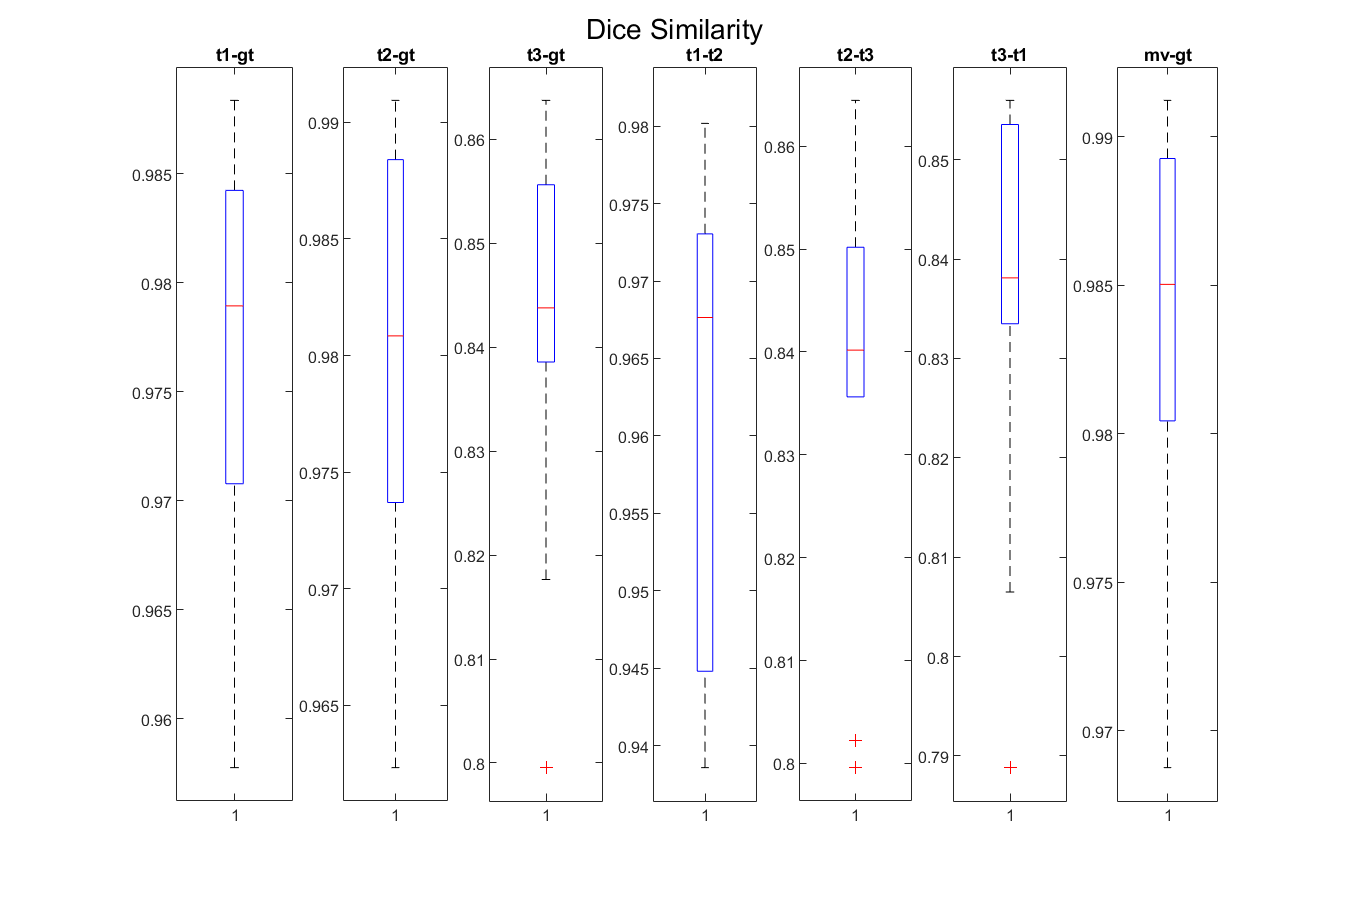

figure('Renderer', 'painters', 'Position', [10 10 900 600]);...
subplot(1,7,1);boxplot(dice_t1_gt_vec); title('t1-gt');...
subplot(1,7,2);boxplot(dice_t2_gt_vec);title('t2-gt');...
subplot(1,7,3); boxplot(dice_t3_gt_vec);title('t3-gt');...
subplot(1,7,4); boxplot(dice_t1_t2_vec);title('t1-t2');...
subplot(1,7,5); boxplot(dice_t2_t3_vec);title('t2-t3');...
subplot(1,7,6); boxplot(dice_t3_t1_vec);title('t3-t1');...
subplot(1,7,7);boxplot(dice_mv_gt_vec);title('mv-gt');...
sgtitle({'Dice Similarity',' '})

## Mean surface distance

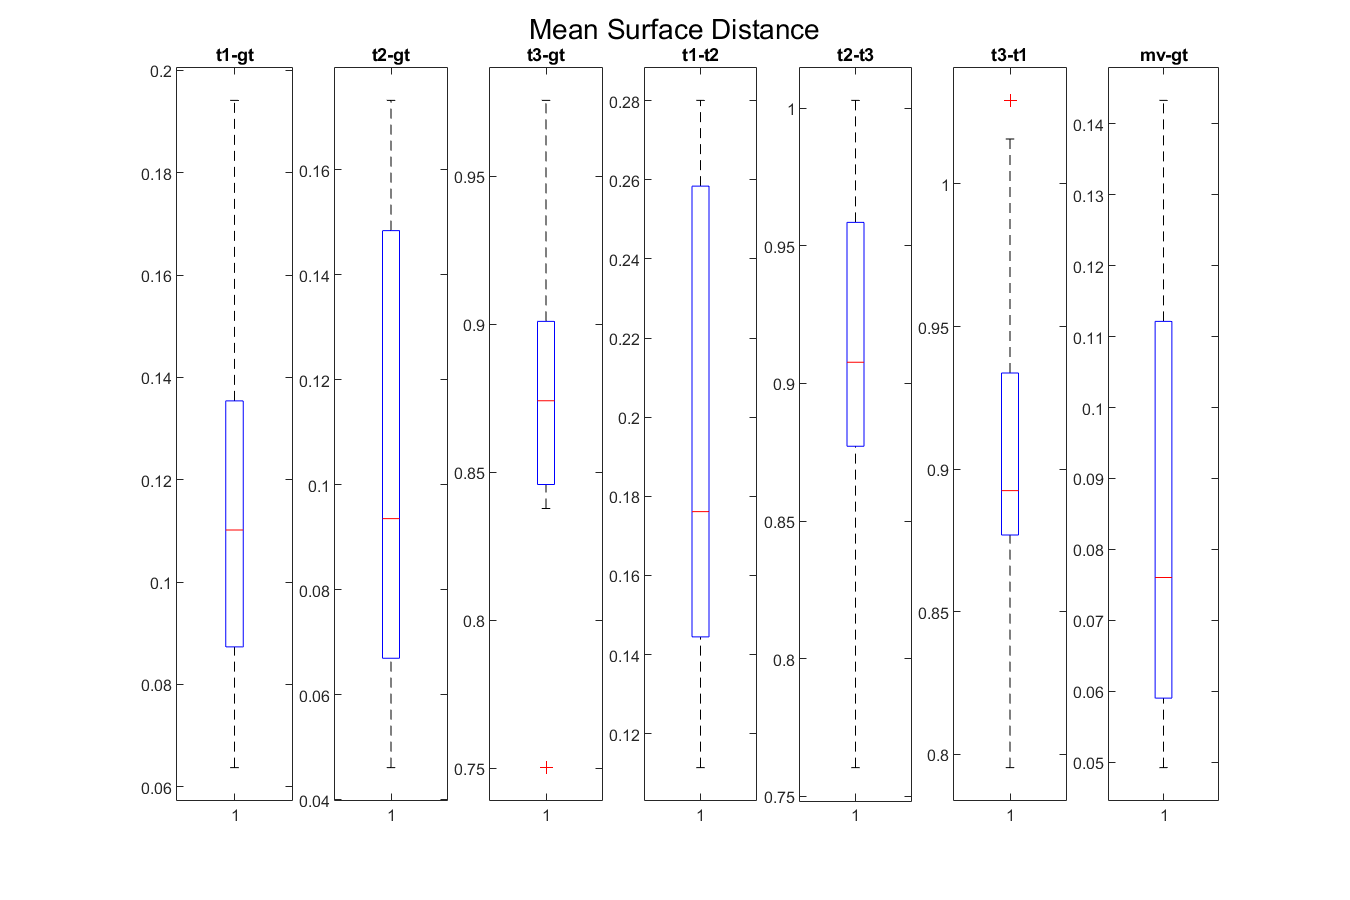

figure('Renderer', 'painters', 'Position', [10 10 900 600]);...
subplot(1,7,1);boxplot(meandist_t1_gt_vec);title('t1-gt');...
subplot(1,7,2);boxplot(meandist_t2_gt_vec);title('t2-gt');...
subplot(1,7,3);boxplot(meandist_t3_gt_vec);title('t3-gt');...
subplot(1,7,4);boxplot(meandist_t1_t2_vec);title('t1-t2');...
subplot(1,7,5);boxplot(meandist_t2_t3_vec);title('t2-t3');...
subplot(1,7,6);boxplot(meandist_t3_t1_vec);title('t3-t1');...
subplot(1,7,7);boxplot(meandist_gt_mv_vec);title('mv-gt');...
sgtitle({'Mean Surface Distance',' '})

## Hausdorff distance

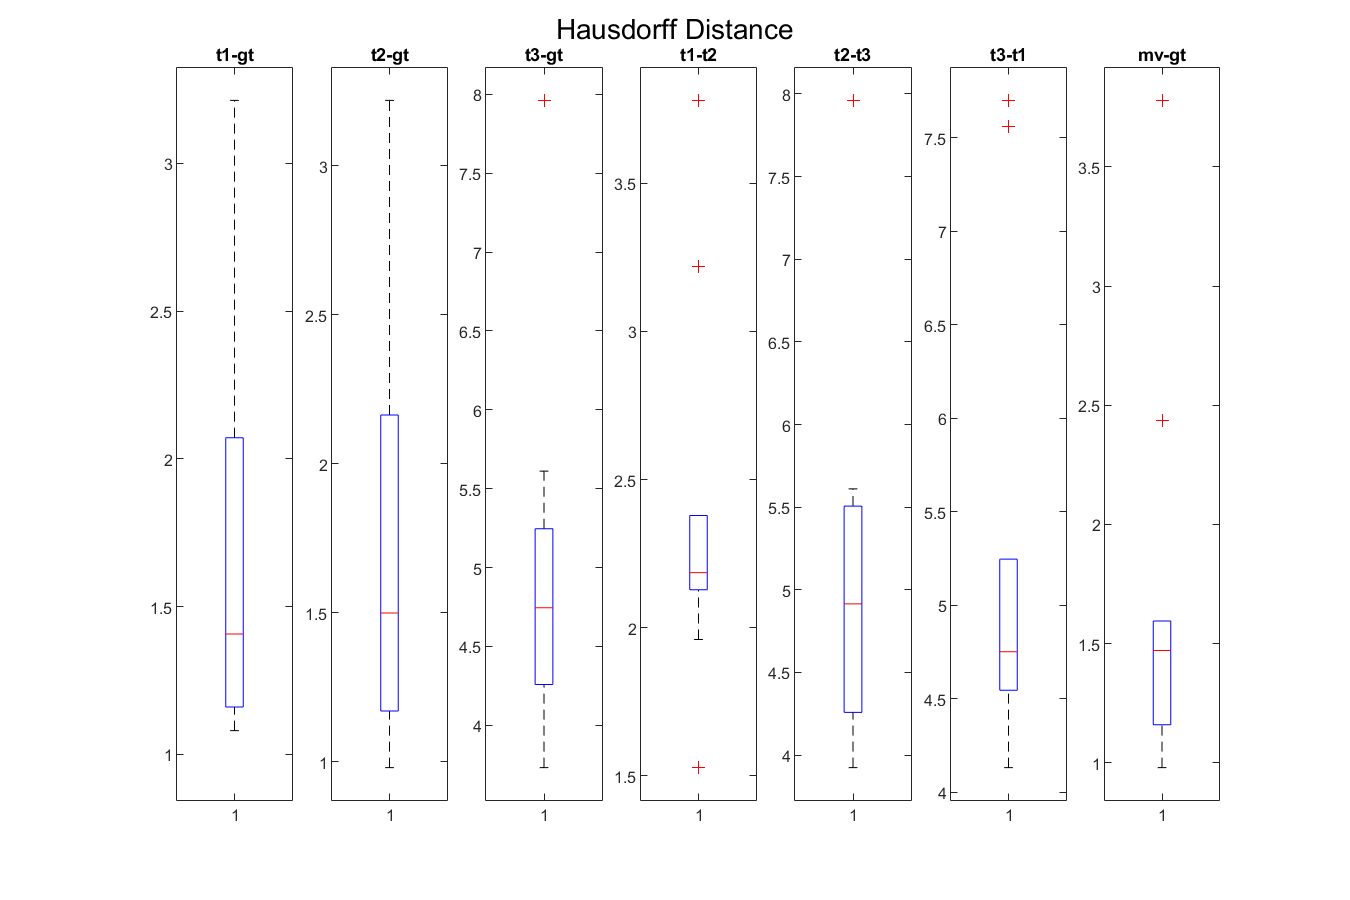

figure('Renderer', 'painters', 'Position', [10 10 900 600]);...
subplot(1,7,1);boxplot(hausdorff_t1_gt_vec);title('t1-gt');...
subplot(1,7,2);boxplot(hausdorff_t2_gt_vec);title('t2-gt');...
subplot(1,7,3);boxplot(hausdorff_t3_gt_vec);title('t3-gt');...
subplot(1,7,4);boxplot(hausdorff_t1_t2_vec);title('t1-t2');...
subplot(1,7,5);boxplot(hausdorff_t2_t3_vec);title('t2-t3');...
subplot(1,7,6);boxplot(hausdorff_t3_t1_vec);title('t3-t1');...
subplot(1,7,7);boxplot(hausdorff_mv_gt_vec);title('mv-gt');...
sgtitle({'Hausdorff Distance',' '})

## 3d) Wilcoxon signed-rank test

[p_volume_1,h_volume_1] = signrank(volume_gts_vec,volume_t1s_vec);
[p_volume_2,h_volume_2] = signrank(volume_gts_vec,volume_t2s_vec);
[p_volume_3,h_volume_3] = signrank(volume_gts_vec,volume_t3s_vec);
[p_volume_mv,h_volume_mv] = signrank(volume_mvs_vec,volume_gts_vec);
[p_volume_12,h_volume_12] = signrank(volume_t1s_vec,volume_t2s_vec);
[p_volume_23,h_volume_23] = signrank(volume_t2s_vec,volume_t3s_vec);
[p_volume_13,h_volume_13] = signrank(volume_t1s_vec,volume_t3s_vec);
[p_volume_mv1,h_volume_mv1] = signrank(volume_t1s_vec,volume_mvs_vec);
[p_volume_mv2,h_volume_mv2] = signrank(volume_t2s_vec,volume_mvs_vec);
[p_volume_mv3,h_volume_mv3] = signrank(volume_t3s_vec,volume_mvs_vec);

T_wil_volume=table([p_volume_1;p_volume_2;p_volume_3;p_volume_mv;p_volume_12;...
    p_volume_23;p_volume_13;p_volume_mv1;p_volume_mv2;p_volume_mv3],...
    [h_volume_1;h_volume_2;h_volume_3;h_volume_mv;h_volume_12;...
    h_volume_23;h_volume_13;h_volume_mv1;h_volume_mv2;h_volume_mv3],...
    'VariableNames',{'p_value','test_decision'},...
    'RowNames',{'gt and t1';'gt and t2';'gt and t3';'gt and mv';'t1 and t2';'t2 and t3';'t1 and t3';...
    't1 and mv';'t2 and mv';'t3 and mv'});

[p_dice_12,h_dice_12] = signrank(dice_t1_gt_vec,dice_t2_gt_vec);
[p_dice_23,h_dice_23] = signrank(dice_t2_gt_vec,dice_t3_gt_vec);
[p_dice_13,h_dice_13] = signrank(dice_t1_gt_vec,dice_t3_gt_vec);
[p_dice_mv1,h_dice_mv1] = signrank(dice_t1_gt_vec,dice_mv_gt_vec);
[p_dice_mv2,h_dice_mv2] = signrank(dice_t2_gt_vec,dice_mv_gt_vec);
[p_dice_mv3,h_dice_mv3] = signrank(dice_t3_gt_vec,dice_mv_gt_vec);
T_wil_dice=table([p_dice_12;p_dice_23;p_dice_13;p_dice_mv1;p_dice_mv2;p_dice_mv3],...
    [h_dice_12;h_dice_23;h_dice_13;h_dice_mv1;h_dice_mv2;h_dice_mv3],...
    'VariableNames',{'p_value','test_decision'},...
    'RowNames',{'t1-gt and t2-gt';'t2-gt and t3-gt';'t1-gt and t3-gt';...
    'mv-gt and t1-gt';'mv-gt and t2-gt';'mv-gt and t3-gt'});

[p_meandist_12,h_meandist_12] = signrank(meandist_t1_gt_vec,meandist_t2_gt_vec);
[p_meandist_23,h_meandist_23] = signrank(meandist_t2_gt_vec,meandist_t3_gt_vec);
[p_meandist_13,h_meandist_13] = signrank(meandist_t1_gt_vec,meandist_t3_gt_vec);
[p_meandist_mv1,h_meandist_mv1] = signrank(meandist_t1_gt_vec,meandist_gt_mv_vec);
[p_meandist_mv2,h_meandist_mv2] = signrank(meandist_t2_gt_vec,meandist_gt_mv_vec);
[p_meandist_mv3,h_meandist_mv3] = signrank(meandist_t3_gt_vec,meandist_gt_mv_vec);
T_wil_meandist=table([p_meandist_12;p_meandist_23;p_meandist_13;p_meandist_mv1;p_meandist_mv2;p_meandist_mv3],...
    [h_meandist_12;h_meandist_23;h_meandist_13;h_meandist_mv1;h_meandist_mv2;h_meandist_mv3],...
    'VariableNames',{'p_value','test_decision'},...
    'RowNames',{'t1-gt and t2-gt';'t2-gt and t3-gt';'t1-gt and t3-gt';...
    'mv-gt and t1-gt';'mv-gt and t2-gt';'mv-gt and t3-gt'});

[p_hausdorff_12,h_hausdorff_12] = signrank(hausdorff_t1_gt_vec,hausdorff_t2_gt_vec);
[p_hausdorff_23,h_hausdorff_23] = signrank(hausdorff_t2_gt_vec,hausdorff_t3_gt_vec);
[p_hausdorff_13,h_hausdorff_13] = signrank(hausdorff_t1_gt_vec,hausdorff_t3_gt_vec);
[p_hausdorff_mv1,h_hausdorff_mv1] = signrank(hausdorff_t1_gt_vec,hausdorff_mv_gt_vec);
[p_hausdorff_mv2,h_hausdorff_mv2] = signrank(hausdorff_t2_gt_vec,hausdorff_mv_gt_vec);
[p_hausdorff_mv3,h_hausdorff_mv3] = signrank(hausdorff_t3_gt_vec,hausdorff_mv_gt_vec);
T_wil_hausdorff=table([p_hausdorff_12;p_hausdorff_23;p_hausdorff_13;p_hausdorff_mv1;p_hausdorff_mv2;p_hausdorff_mv3],...
    [h_hausdorff_12;h_hausdorff_23;h_hausdorff_13;h_hausdorff_mv1;h_hausdorff_mv2;h_hausdorff_mv3],...
    'VariableNames',{'p_value','test_decision'},...
    'RowNames',{'t1-gt and t2-gt';'t2-gt and t3-gt';'t1-gt and t3-gt';...
    'mv-gt and t1-gt';'mv-gt and t2-gt';'mv-gt and t3-gt'});

fprintf('Wilcoxon signed-rank test for volume\n\n');disp(T_wil_volume)

Wilcoxon signed-rank test for volume

                  p_value     test_decision
                 _________    _____________

    gt and t1       0.8457        false    
    gt and t2      0.69531        false    
    gt and t3    0.0019531        true     
    gt and mv      0.49219        false    
    t1 and t2      0.76953        false    
    t2 and t3    0.0019531        true     
    t1 and t3    0.0019531        true     
    t1 and mv      0.69531        false    
    t2 and mv      0.92188        false    
    t3 and mv    0.0019531        true     



fprintf('Wilcoxon signed-rank test for dice similarity\n\n'); disp(T_wil_dice)

Wilcoxon signed-rank test for dice similarity

                        p_value     test_decision
                       _________    _____________

    t1-gt and t2-gt      0.23242        false    
    t2-gt and t3-gt    0.0019531        true     
    t1-gt and t3-gt    0.0019531        true     
    mv-gt and t1-gt    0.0019531        true     
    mv-gt and t2-gt     0.048828        true     
    mv-gt and t3-gt    0.0019531        true     



fprintf('Wilcoxon signed-rank test for mean surface distance\n\n'); disp(T_wil_meandist)

Wilcoxon signed-rank test for mean surface distance

                        p_value     test_decision
                       _________    _____________

    t1-gt and t2-gt      0.32227        false    
    t2-gt and t3-gt    0.0019531        true     
    t1-gt and t3-gt    0.0019531        true     
    mv-gt and t1-gt    0.0019531        true     
    mv-gt and t2-gt     0.048828        true     
    mv-gt and t3-gt    0.0019531        true     



fprintf('Wilcoxon signed-rank test for Hausdorff distance\n\n'); disp(T_wil_hausdorff)

Wilcoxon signed-rank test for Hausdorff distance

                        p_value     test_decision
                       _________    _____________

    t1-gt and t2-gt            1        false    
    t2-gt and t3-gt    0.0019531        true     
    t1-gt and t3-gt    0.0019531        true     
    mv-gt and t1-gt      0.76953        false    
    mv-gt and t2-gt      0.65234        false    
    mv-gt and t3-gt    0.0019531        true     



In the cases that involve target 3, null hypothesis is rejected. Which means that the distribution of the target 3 segmentation is not similar to ground truth, target 1 and target 2 segmentations.

## 3e) The confusion matrix, sensitivity and specificity is shown in Task 2a and 2b

## Used Functions

function dc=dice(data1,data2)
% calculate dice
tp=sum(sum(sum((data1 & data2))));
fp=sum(sum(sum((~data1 & data2))));
%tn=sum(sum(sum((~data1 & ~data2))));
fn=sum(sum(sum((data1 & ~data2))));
dc=2*tp/(2*tp+fp+fn);
end

function [mn1,mn2,mx1,mx2]=SurfaceDistance(gts,t1s)
% calculates mean surface distance
show_eta=0 ;
points=gts.vertices;
dist_gt2t1_min=1000*ones(1,length(points));
tic
for i=1:length(t1s.faces)
    dist=Points2TriangleDistance(t1s.vertices,t1s.faces(i,:),points);
    elapsed=toc;
    dist_gt2t1_min(dist_gt2t1_min>dist)=dist(dist_gt2t1_min>dist);
    if show_eta
        if mod(i,500)==0
            disp(['forward pass eta: ',num2str(elapsed/i*(length(t1s.faces)-i)/60) ' minutes'])
        end
    end
end

points=t1s.vertices;
dist_t12gt_min=1000*ones(1,length(points));
tic
for i=1:length(gts.faces)
    dist=Points2TriangleDistance(gts.vertices,gts.faces(i,:),points);
    elapsed=toc;
    dist_t12gt_min(dist_t12gt_min>dist)=dist(dist_t12gt_min>dist);
    if show_eta
        if mod(i,500)==0
            disp(['backward pass eta: ',num2str(elapsed/i*(length(gts.faces)-i)/60) ' minutes'])
        end
    end
end
mn1=mean(dist_gt2t1_min);
mn2=mean(dist_t12gt_min);
mx1=max(dist_gt2t1_min);
mx2=max(dist_t12gt_min);
end


function [meandist, hausdorff]=mean_hausdorff(label1,label2)
[mn1,mn2,mx1,mx2]=SurfaceDistance(label1,label2);
meandist=mean([mn1,mn2]);
hausdorff=max([mx1,mx2]);
end

function dist=Points2TriangleDistance(vertices, face,points)
% calculates minimum distance of all points from a single triangular surface
q1=vertices(face(1),:)';
q2=vertices(face(2),:)';
q3=vertices(face(3),:)';
v1=q2-q1; v2=q3-q1;
V=[v1 v2];
coeff=V\(points'-q1);
dist_vect=points'-(q1+V*coeff);
dist=vecnorm(dist_vect);
ind_rem=~(coeff(1,:)>=0 & coeff(2,:)>=0 & sum(coeff)<=1);
points_rem=points(ind_rem,:);
v3=q3-q2;

d=v1'*(points_rem'-q1)/vecnorm(v1)^2;
d(d>1)=1; d(d<0)=0;
e=v2'*(points_rem'-q1)/vecnorm(v2)^2;
e(e>1)=1; e(e<0)=0;
f=v3'*(points_rem'-q2)/vecnorm(v3)^2;
f(f>1)=1; f(f<0)=0;

d1=vecnorm(points_rem'-(q1+v1*d));
d2=vecnorm(points_rem'-(q1+v2*e));
d3=vecnorm(points_rem'-(q2+v3*f));
d_vect=[d1;d2;d3];
dist(ind_rem)=min(d_vect);
end

function d=vecnorm(v)
% calculates euclidean norm
d=sqrt(sum(v.^2));
end

function [tp,fp,tn,fn]=class_perf(data1,data2)
% calculates tp, fp, tn, fn from ground truth and target
tp=sum(sum(sum((data1 & data2))));
fp=sum(sum(sum((~data1 & data2))));
tn=sum(sum(sum((~data1 & ~data2))));
fn=sum(sum(sum((data1 & ~data2))));
end

function V=VolumeofMesh(O)
% calculates volume of a mesh
V=0;
for i=1:length(O.faces)
    v1=O.vertices(O.faces(i,1),:);
    v2=O.vertices(O.faces(i,2),:);
    v3=O.vertices(O.faces(i,3),:);
    V=V+...
    (-v3(1)*v2(2)*v1(3)...
    +v2(1)*v3(2)*v1(3)...
    +v3(1)*v1(2)*v2(3)...
    -v1(1)*v3(2)*v2(3)...
    -v2(1)*v1(2)*v3(3)...
    +v1(1)*v2(2)*v3(3))/6;
end
V=abs(V);
end
